cd ~/Documents/Polimi/IACVHomework/
I = imread('villa.png');
sunPosition = [3.9; -1; 0; 0];
cameraHeight = 1.5;

# Feature extraction

## Equalization and Contrast + Smoothing

To obtain the best results, we equalize the histogram of the input image

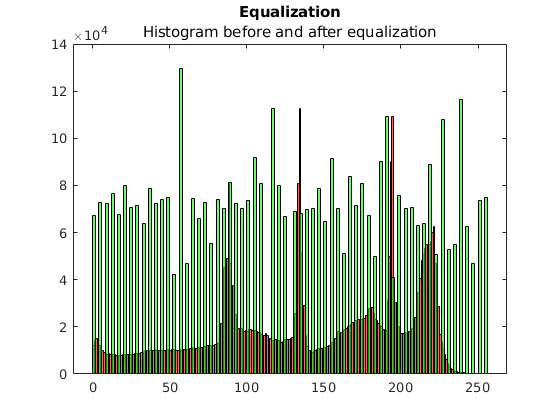

Ieq = histeq(I);
figure, histogram(I, 'FaceColor', 'red'), hold on, histogram(Ieq, 'FaceColor', 'green'), title('Equalization', 'Histogram before and after equalization');

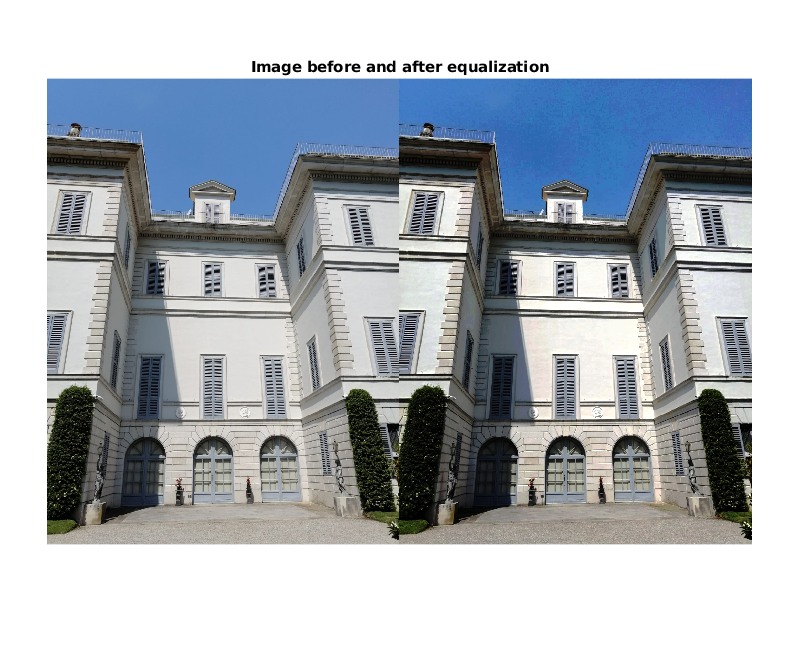

figure, imshowpair(I, Ieq, 'montage'), title('Image before and after equalization');

After equalization the contrast is enhanced, but we can rise it a bit more to highlight better elements like the borders of the windows. We use a local laplacian filter for this, to perform an edge-aware operation that also helps smoothing the noise of the sky and the walls

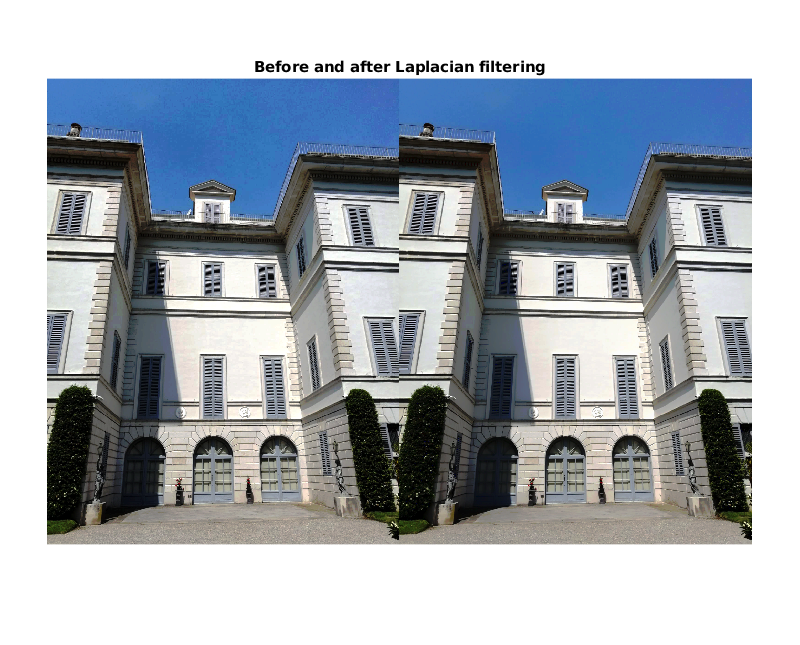

C = locallapfilt(Ieq, 0.1, 2);
figure, imshowpair(Ieq,C, 'montage'), title('Before and after Laplacian filtering')

## Thresholding

From the analysys of the histogram of the bw image we observe three main peaks. Because of this, it's hard to apply a global threshold.

This result was expected, as we are dealing with an image taken under natural sunlight, therefore with shadows and other lighting variations.

We will then use a local thresholding to obtain better results.

BW = rgb2gray(C);

The result of this thresholding enhances very well the edges of the building thanks to the shadows. We must however be careful to mix features coming from shadows and real edges.

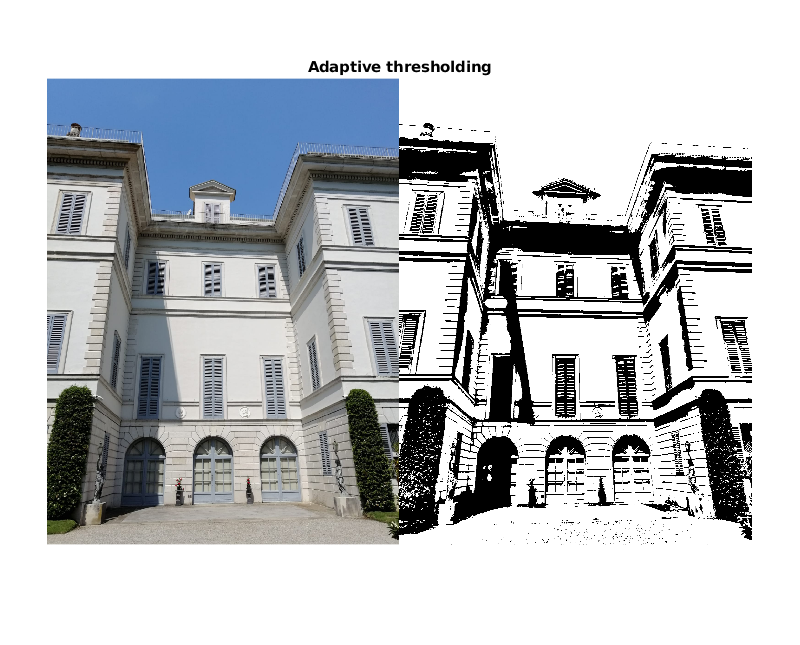

Tvalue = adaptthresh(BW, 0.7);   % Find the best threshold value
T = imbinarize(BW, Tvalue); % Apply thresholding
figure, imshowpair(I, T, "montage"), title("Adaptive thresholding");

We want to give the best input possible to the edge detector, so we can remove some noise.

Because the image is binary, we can use a min filter (erosion).

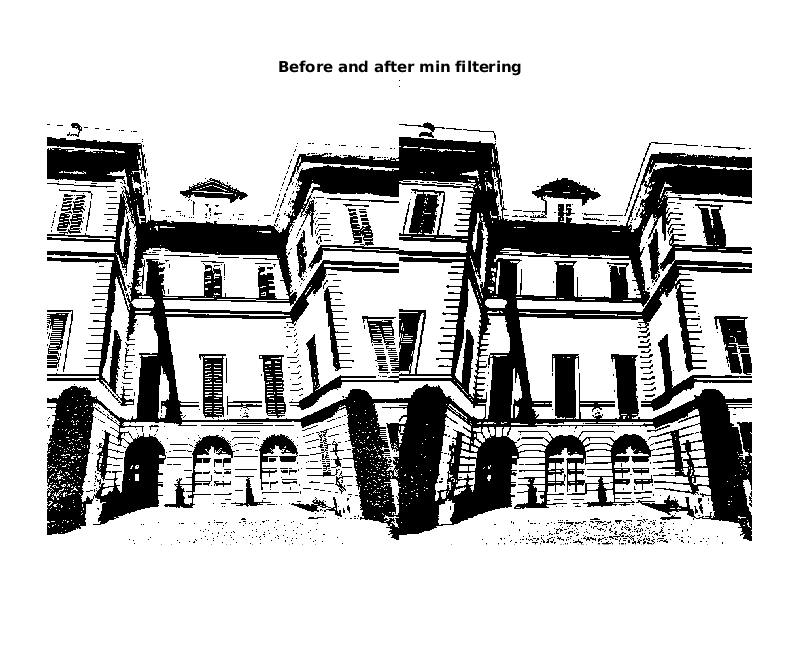

Tmin = imerode(T, strel('square', 3));
figure, imshowpair(T, Tmin, 'montage'), title("Before and after min filtering");

## Edges detection

Because our image is already binary, finding the edges is easy, as we only need to find the borders between black and white areas (all ramp or spike edges). 

The two most intuitive solutions are:

- Canny, because of its versatility and more robustness to noise. However, this seems be not only an overkill, but also counterproductive because of its gaussian smoothing;

- Sobel, as it is simpler, so it could perform good with a binary image.

However, we observe that the results with both methods don't change much, and are good but not the best.

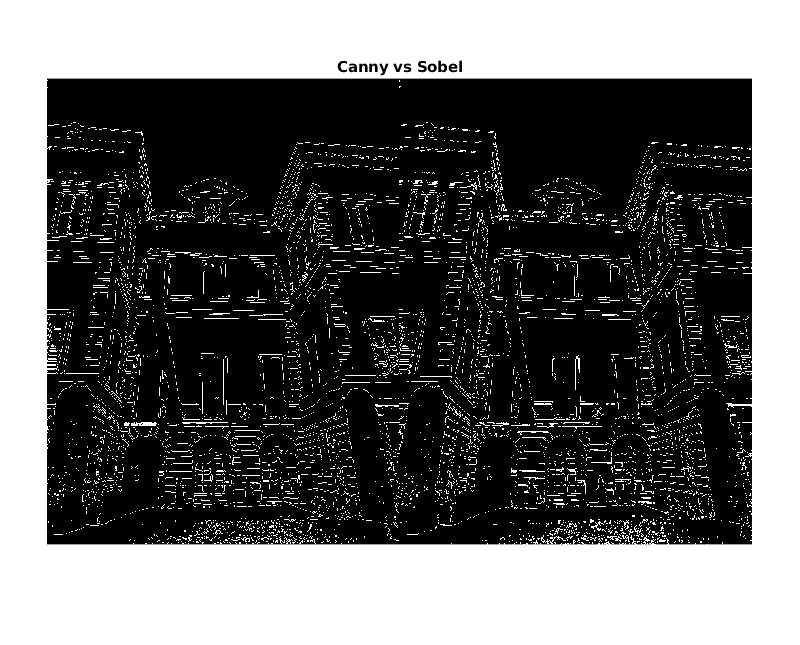

EtSobelH = edge(Tmin, 'sobel', 'horizontal');
EtSobelV = edge(Tmin, 'sobel', 'vertical');
EtSobel = EtSobelV | EtSobelH;
EtCanny = edge(Tmin, 'canny');       % For comparison
figure, imshowpair(EtCanny, EtSobel,'montage'), title('Canny vs Sobel');

We can actually get better results by taking the image masked by its dilation, indeed we see that the connectivity is improved with this method.

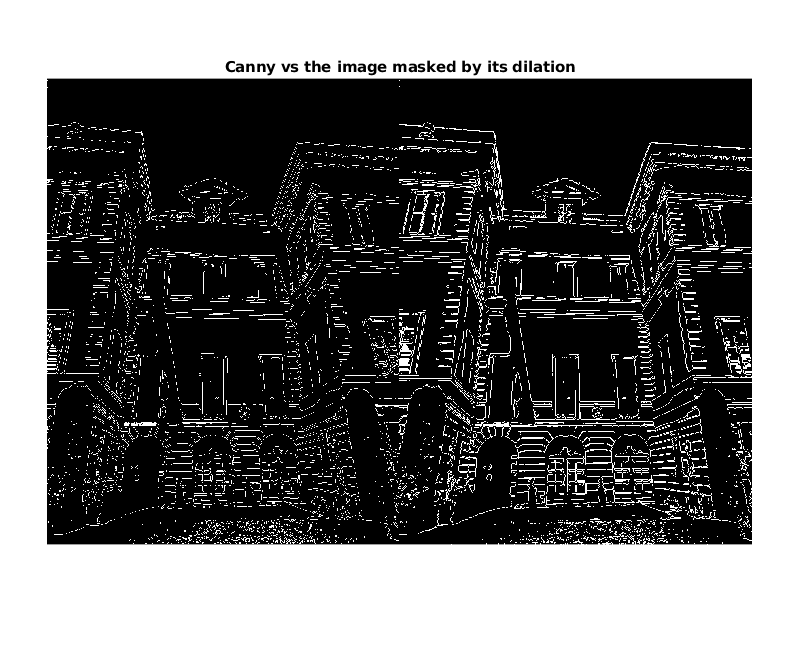

EtPoor = bitxor(imdilate(Tmin, strel('disk', 2)), Tmin);
figure, imshowpair(EtCanny, EtPoor, 'montage'), title("Canny vs the image masked by its dilation");

## Features

Use the Hough transform to identify the straight lines

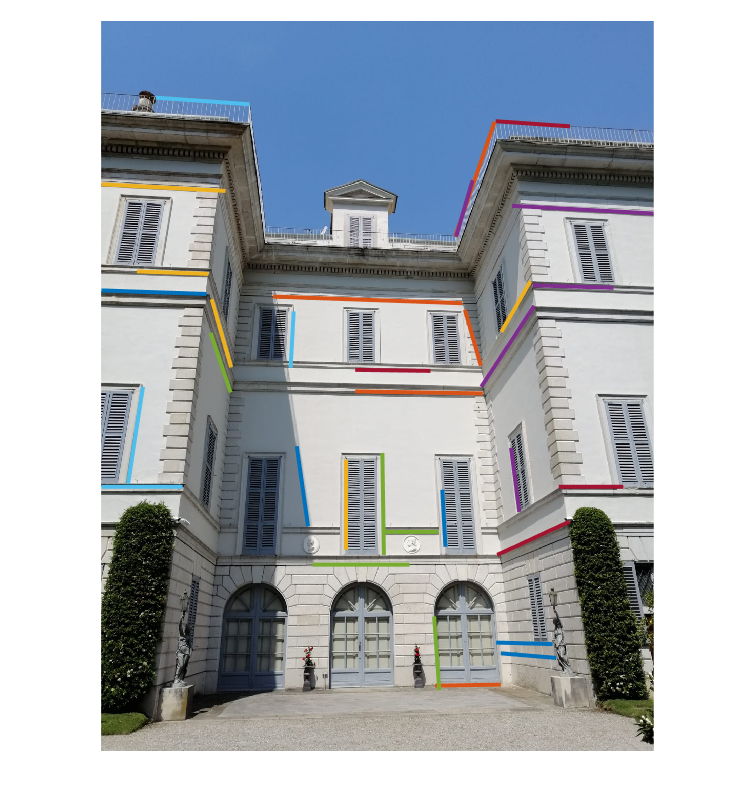

[H, theta, rho] = hough(EtPoor); 
hgPeaks = houghpeaks(H, 200, 'Theta', theta, 'Threshold', 0.2 * max(H(:)));     % identify the peaks in the diagram, which correspond to candidate lines
hgLines = houghlines(EtPoor, theta, rho, hgPeaks,'FillGap', 5, 'MinLength', size(I, 2) * 0.1); 
figure, imshow(I), hold on;
for k = 1:length(hgLines)
    pts = [hgLines(k).point1; hgLines(k).point2];
    plot(pts(:,1), pts(:,2), 'LineWidth',3);
end

Detect also the corners

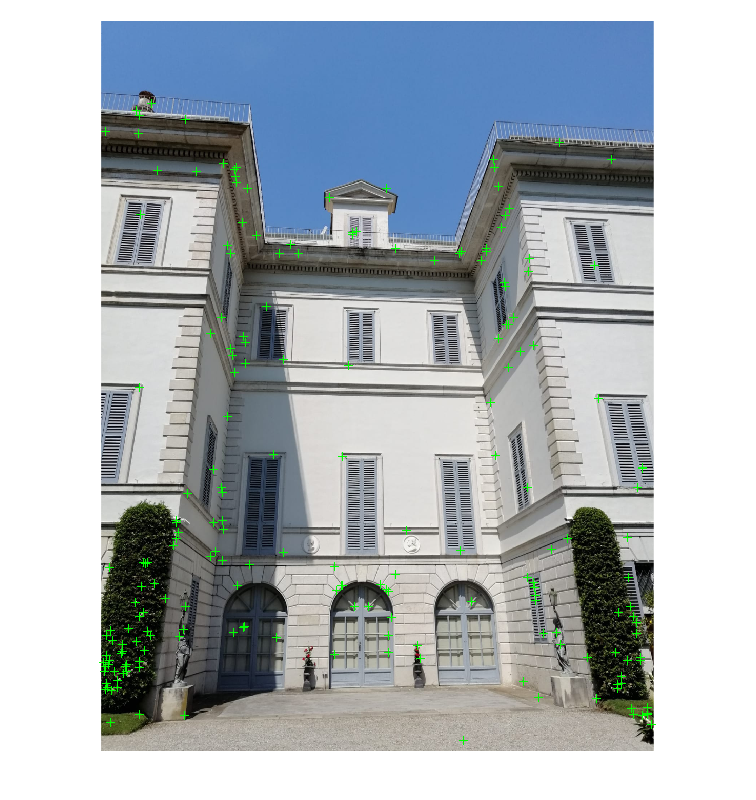

corners = detectHarrisFeatures(EtPoor);
figure, imshow(I), hold on, plot(corners.selectStrongest(200));

# 2D reconstruction of a horizontal section

function selectLines(I, hgLines, arr)
    set(gcf,'Visible','on')
    figure, imshow(I), hold on;
    for k = 1:length(hgLines)
        pts = [hgLines(k).point1; hgLines(k).point2];
        roi = drawline('Position', pts);
        addlistener(roi, 'ROIClicked', @(src, evnt)allevents(src, evnt, arr));
    end
end


function allevents(src, evt, varargin)
    evName = evt.EventName;
    switch (evName)
        case{'ROIClicked'}
            %disp('roi clicked');
            arr = varargin{1};
            src.Color = [0.5, 0.5, 0.5];
            arr(3) = src;
            disp(arr)
    end
end

